clc
clear

**Kmeans**

a) Generate a 2D uncorrelated Gaussian distributed training dataset

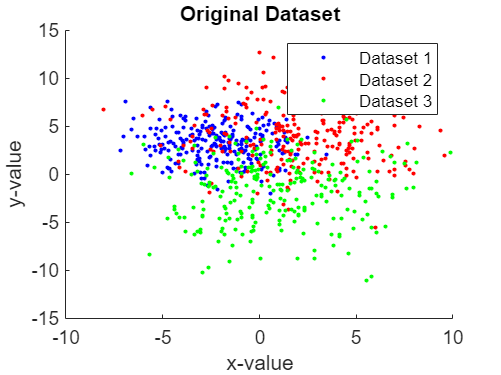

samples = 250;

%cluster 1 
mean1 = [-2; 3];
sd1 = 2;

%cluster 2
mean2 = [2; 4];
sd2 = 3;

%cluster 3
mean3 = [1; -2];
sd3 = 3.25;

dataset1 = sd1 * randn(2,samples) + repmat(mean1,1,samples);
dataset2 = sd2 * randn(2,samples) + repmat(mean2,1,samples);
dataset3 = sd3 * randn(2,samples) + repmat(mean3,1,samples);

%plot
hold on
plot(dataset1(1,:),dataset1(2,:),'b.')
plot(dataset2(1,:),dataset2(2,:),'r.')
plot(dataset3(1,:),dataset3(2,:),'g.')
xlabel('x-value')
ylabel('y-value')
title("Original Dataset")
legend('Dataset 1','Dataset 2','Dataset 3')
hold off

b) Concatenate the datasets into a single dataset and plot all the points

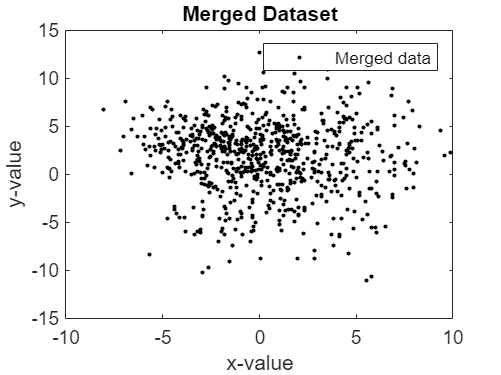

ConCluster = cat(2,dataset1,dataset2,dataset3);

plot(ConCluster(1,:),ConCluster(2,:),'black.')
title("Merged Dataset")
legend('Merged data')
xlabel('x-value')
ylabel('y-value')

c) Given the number of clusters as 3, implement Kmeans clustering from first principles

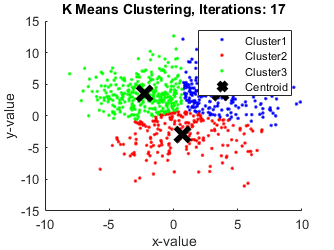

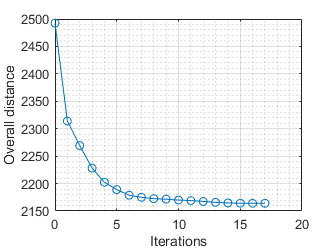

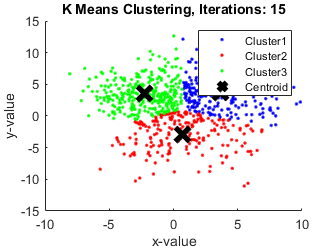

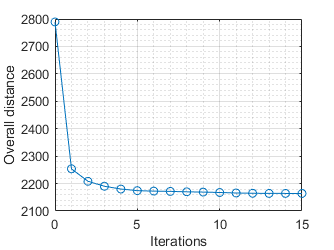

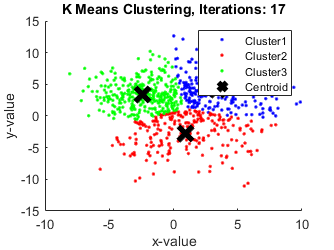

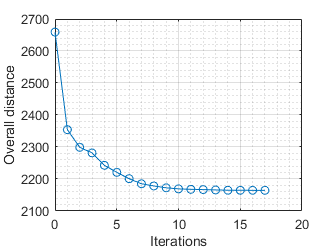

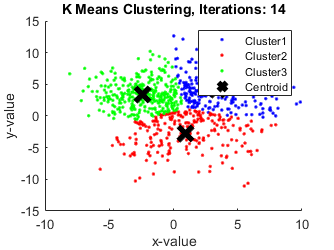

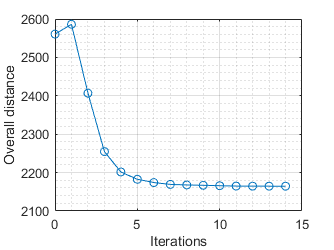

%select the number of clusters you want to identify in your data.
%this is the k in k-means clustering
k=3;
max_iterations = 10;
newCluster1 = [];
newCluster2 = [];
newCluster3 = [];

for j = 1:max_iterations
    done = false;
    iteration=0;
    totalDistances = [];
    totalDistance = 0;
    %step2 randomly select 3 destinct datapoints -> these are the initical clusters
    
    r1 = (randi([1,size(ConCluster,2)],1));
    r2 = (randi([1,size(ConCluster,2)],1));
    r3 = (randi([1,size(ConCluster,2)],1));

    centroid1 = [ConCluster(1,r1);ConCluster(2,r1)];
    centroid2 = [ConCluster(1,r2);ConCluster(2,r2)];
    centroid3 = [ConCluster(1,r3);ConCluster(2,r3)];

    for i  = 1:size(ConCluster,2)
        %step 3 Measure the distances between the 1st point and the three initial
        %clusters
        dist1 = sqrt((centroid1(1,1)-ConCluster(1,i))^2+(centroid1(2,1)-ConCluster(2,i))^2);
        dist2 = sqrt((centroid2(1,1)-ConCluster(1,i))^2+(centroid2(2,1)-ConCluster(2,i))^2);
        dist3 = sqrt((centroid3(1,1)-ConCluster(1,i))^2+(centroid3(2,1)-ConCluster(2,i))^2);

        %step 4 Assign the first point to the nearest cluster -> do the same for
        %the next point
        %-> measure the distances and assign the point to the nearest cluster
        if dist1 < dist2 && dist1 < dist3
            newCluster1 = [newCluster1, [ConCluster(1,i);ConCluster(2,i)]];
            totalDistance = totalDistance + dist1;
        elseif (dist2 < dist3 && dist2 < dist1)
            newCluster2 = [newCluster2, [ConCluster(1,i);ConCluster(2,i)]];
            totalDistance = totalDistance + dist2;
        else
            newCluster3 = [newCluster3, [ConCluster(1,i);ConCluster(2,i)]];
            totalDistance = totalDistance + dist3;
        end
    end
    totalDistances = [totalDistances,[iteration;totalDistance]];
    
    while done==false
        iteration = iteration +1;
        totalDistance = 0;
        %step 5 calculate the mean of each cluster
        %repeat what just did (measure and cluster) using the mean values
        %sum of rows
        c1Size = size(newCluster1,2);
        c2Size = size(newCluster2,2);
        c3Size = size(newCluster3,2);

        newCentroid1 = [(sum(newCluster1(1,:)))/c1Size;(sum(newCluster1(2,:)))/c1Size];
        newCentroid2 = [(sum(newCluster2(1,:)))/c2Size;(sum(newCluster2(2,:)))/c2Size];
        newCentroid3 = [(sum(newCluster3(1,:)))/c3Size;(sum(newCluster3(2,:)))/c3Size];
        
        newCluster1 = [];
        newCluster2 = [];
        newCluster3 = [];
        for i  = 1:size(ConCluster,2)
            dist1 = sqrt((newCentroid1(1,1)-ConCluster(1,i))^2+(newCentroid1(2,1)-ConCluster(2,i))^2);
            dist2 = sqrt((newCentroid2(1,1)-ConCluster(1,i))^2+(newCentroid2(2,1)-ConCluster(2,i))^2);
            dist3 = sqrt((newCentroid3(1,1)-ConCluster(1,i))^2+(newCentroid3(2,1)-ConCluster(2,i))^2);
           
            if dist1 < dist2 && dist1 < dist3
                newCluster1 = [newCluster1, [ConCluster(1,i);ConCluster(2,i)]];
                totalDistance = totalDistance + dist1;
            elseif (dist2 < dist3 && dist2 < dist1)
                newCluster2 = [newCluster2, [ConCluster(1,i);ConCluster(2,i)]];
                totalDistance = totalDistance + dist2;
            else
                newCluster3 = [newCluster3, [ConCluster(1,i);ConCluster(2,i)]];
                totalDistance = totalDistance + dist3;
            end
        end
        totalDistances = [totalDistances,[iteration;totalDistance]];
        totalDistance = 0;

        %if clustering does not change during iteration then k-means is complete
        if (centroid1 == newCentroid1 & centroid2 == newCentroid2 & centroid3 == newCentroid3)
            %stop 
            done=true;
            figure
            hold on
            plot(newCluster1(1,:),newCluster1(2,:),'b .')
            plot(newCluster2(1,:),newCluster2(2,:),'r .')
            plot(newCluster3(1,:),newCluster3(2,:),'g .')
            plot(newCentroid1(1,1),newCentroid1(2,1),'black x','MarkerSize',15,'linewidth',4)
            plot(newCentroid2(1,1),newCentroid2(2,1),'black x','MarkerSize',15,'linewidth',4)
            plot(newCentroid3(1,1),newCentroid3(2,1),'black x','MarkerSize',15,'linewidth',4)
            titleName = append('K Means Clustering, Iterations: ',int2str(iteration));
            title(titleName)
            legend('Cluster1','Cluster2','Cluster3','Centroid')
            xlabel('x-value')
            ylabel('y-value')
            hold off
            %plot distances and iterations
            figure
            title('Overall distances vs. number of iterations')
            xlabel('Overall distances')
            ylabel('Iterations')
            plot(totalDistances(1,:),totalDistances(2,:),'o-')
            grid on
            grid minor
            xlabel('Iterations')
            ylabel('Overall distance')
            totalDistances = [];
        else
            %continue
            centroid1 = newCentroid1;
            centroid2 = newCentroid2;
            centroid3 = newCentroid3;
            done = false;
        end
    end
        
end



%can assess the quality of the clustering by adding up the variation within
%each cluster

%keep track of these clusters and their total varience and do the whole
%thing over with different starting points


d) If the number of clusters is unknown, explain and find out (via matlab code) the best number of clusters.

%Elbow plot
%calculate how bad it is with total variation -> 
%calculate variation
%calcVariation([6,9,14,10,5,8,11])
%k = 3;
%l = temp(ConCluster,k)

function [variation] = calcVariation(a)
    %a = [6,9,14,10,5,8,11];
    s = size(a,2);
    b = 0;
    for i = 1:size(a,2)
        b = b + ((a(i)-mean(a))^2);
    end
    %variation = ((a[i]-mean(a[i]))^2)
    variation = b/size(a,2)
end

e) From  your  observation  and  analysis,  what  are  the  limitations  or  drawbacks  of  Kmeans clustering?  

%